# calculate the optimal Fisher Information for a certain tumour position

clc
clear
addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\iso2mesh'))

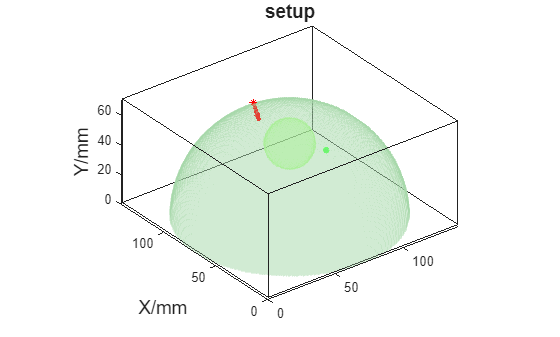

%% 2D CSF simulation main simulation
save_flag = 0; % 0 is not saving any picture
clear cfg;

% % % % general setting
cfg.nphoton = 1e8;
cfg.gpuid = '11'; % use two GPUs
cfg.workload = [10,10];  % evenly use the two GPUs
cfg.autopilot = 1;
cfg.maxdetphoton = cfg.nphoton;
brain_radius = 70;
cfg.vol = uint8(zeros([brain_radius*2,brain_radius*2,brain_radius])); % 3D simulation
cfg.tstart = 0;
cfg.tend = 5e-9;
cfg.tstep = 5e-9;
cfg.debuglevel = 'P'; % show progress bar
cfg.unitinmm = 1;
cfg.issrcfrom0 = 0;  % 1-first voxel is [0 0 0], [0]- first voxel is [1 1 1]
% % % % general setting end

% % % % build indices for the voxels, use voxel center
center_pos = [brain_radius brain_radius 0];
[grid_x,grid_y,grid_z] = ndgrid(linspace(1,2*brain_radius,size(cfg.vol,1)),linspace(1,2*brain_radius,size(cfg.vol,2)), ...
    linspace(1,brain_radius,size(cfg.vol,3)));

dmua = 0.02; % difference in mua because of tumour

% % % % set brain segmentation
% % % % type [0 air, 1 GM, 2 CSF]
cfg.prop = [0 0 1 1;
    0.033 1 0 1.33;
    0.033+dmua 1 0 1.33];

D_from_center = sqrt((grid_x-center_pos(1)).^2+(grid_y-center_pos(2)).^2+(grid_z-center_pos(3)).^2);

cfg.vol(find(D_from_center<=70))=uint8(1);

% % % % source set---------------------------------------
source_radius = brain_radius; source_angle_rad =  pi/3;
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
meas_radius = brain_radius; meas_angle_rad =  pi/6+pi/2; % pi/2 -0.5 pi/2+0.01
mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
cfg.srcpos = [brain_radius, brain_radius+src_pos(1), src_pos(2)];
cfg.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)
cfg.srctype = 'pencil';
% % % %  source set end-----------------------------------

% % % % det set
cfg.detpos = [brain_radius, brain_radius+mea_pos(1), +mea_pos(2), 2];
% % % %  det set end

tumour_pos = [70 70 50];
tumour_rad = 15;
D_from_tu = sqrt((grid_x-tumour_pos(1)).^2+(grid_y-tumour_pos(2)).^2+(grid_z-tumour_pos(3)).^2);
cfg.vol(find(D_from_tu<=tumour_rad))=uint8(2);

% % % % show the setup
figure,mcxpreview(cfg); title('setup',FontSize=14);
ylabel('X/mm',FontSize=14)
zlabel('Y/mm',FontSize=14)

## run the simulation of distance0

cfg.outputtype = 'flux';
% cfg_csf.outputtype = 'jacobian';
rng('default')

source_angle = linspace(-pi/2,0,1)';
det_angle = linspace(0,pi,2)';
weight = zeros(size(det_angle,1)*size(source_angle,1),1);
weight_p = zeros(size(det_angle,1)*size(source_angle,1),1);

for i = 1:size(det_angle,1)*size(source_angle,1)

    [im,is] = ind2sub([size(det_angle,1),size(source_angle,1)],i);

    source_radius = brain_radius; source_angle_rad =  source_angle(is);
    meas_radius = brain_radius; meas_angle_rad = det_angle(im) ;

    src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
    mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
    cfg.srcpos = [brain_radius, brain_radius+src_pos(1), src_pos(2)];
    cfg.detpos = [brain_radius, brain_radius+mea_pos(1), mea_pos(2), 2];
    cfg.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)


    [~, detp_csf, ~, ~] = mcxlab(cfg);
    if isempty(detp_csf.ppath)
        weight(i) = sum(mcxdetweight(detp_csf,cfg.prop,cfg.unitinmm));
        prop_p = cfg.prop;
        prop_p(3,1) = prop_p(3,1) + dmua;
        weight_p(i) = sum(mcxdetweight(detp_csf,prop_p,cfg.unitinmm));
    else
        weight(i) = 0;
        weight_p(i) = 0;
    end

end

Unrecognized function or variable 'mcx'.

Error in mcxlab (line 517)
    [varargout{1:max(1, nargout)}] = mcx(varargin{1});
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

## data post-process and calculate FI

% Convert amplitude to counts per second (cps)
% input_power_density = 3e-3; % maximum safty threshold 3mw/mm^2
addpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\tomography241015\NIRfast_code_241118\nirfast_fisher_numerical_311224')
input_power_v = [1e-4 5e-4 1e-3 3e-3]; % W/mm^2
% input_power_v = [1e-7 1e-6 1e-5 1e-4]; % W/mm^2
% input_power_v = [1e-10];
amplitude = weight./cfg.nphoton;
amplitude_p = weight_p./cfg.nphoton;

Fisher_result_batch_csf = zeros(length(amplitude),length(input_power_v));
PC_batch_csf = zeros(length(amplitude),length(input_power_v));
dIdmua_batch_csf = zeros(length(amplitude),length(input_power_v));
ind_result = 1;

for input_power_density =  input_power_v

    h = 6.626e-34; % Planck constant in Js
    lambda = 800e-9; % wavelength in m
    sp_eng = h.*wavelen2freq(lambda); % single photon energy
    exposure_time = 0.1;
    bandwidth = 1/exposure_time/2;
    photon_counts = round(amplitude.*input_power_density/sp_eng*exposure_time*1); % exposure time 0.1s and area 1mm^2
    photon_counts_p = round(amplitude_p.*input_power_density/sp_eng*exposure_time*1); % exposure time 0.1s and area 1mm^2

    PC_batch_csf(:,ind_result) = photon_counts;

    pc_threshold = 1e8*exposure_time; % the threshold of SPAD max cps
    dI_dmua = (amplitude_p.*input_power_density/sp_eng*exposure_time*1-amplitude.*input_power_density/sp_eng*exposure_time*1)./dmua; % calculate how the intensity change with tumour radius
    dI_dmua = dI_dmua.*(abs(dI_dmua)>1);

    dIdmua_batch_csf(:,ind_result) = dI_dmua;

    % % % % distinguish according to threshold
    Poisson_ind = photon_counts<=pc_threshold;
    Gaussian_ind = photon_counts>pc_threshold;

    % % % % gaussian noise level
    nep = 1e-13; % W/sqrt(Hz)
    Gaussian_std = nep*sqrt(bandwidth)/sp_eng*exposure_time;
    % std of CPS, exposure time 0.1s

    Fisher_result = dI_dmua.^2.*1./photon_counts.*Poisson_ind; % Poisson noise
    Fisher_result(isnan(Fisher_result)) = 0;

    % % % % Gaussian noise+poisson noise
    parfor_progress(length(Fisher_result(:)));
    % for i = 1:length(Fisher_result(:))
    parfor (i = 1:length(Fisher_result(:)),4)
        if Gaussian_ind(i) == 1
            Fisher_result(i) = calculate_Gau_Pos_FI(Gaussian_std,photon_counts(i),dI_dmua(i));
        end
        parfor_progress;
    end

    parfor_progress(0);
    Fisher_result_batch_csf(:,ind_result) = Fisher_result;
    ind_result = ind_result+1;
end

## show result

figure;
for i = 1:size(Fisher_result_batch_csf,2)
    plot((Fisher_result_batch_csf(:,i)),LineWidth=2);hold on
end
xlabel("S-D pair flag")
ylabel('Fisher Information')
ax = gca; ax.FontSize = 20;
title('Fisher Information VS power&S-D pair')

legend_str = '';
for i = 1:length(input_power_v)
    legend_str{end+1} = sprintf('input power = %0.2fmw',input_power_v(i)*1e3);
end

legend(legend_str,'Fontsize',15)

target_sd_pair = 41;

[im,is] = ind2sub([size(det_angle,1),size(source_angle,1)],target_sd_pair);

source_radius = 54; source_angle_rad =  source_angle(is);
meas_radius = 54; meas_angle_rad =  det_angle(im) ;
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
cfg.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
cfg.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 1];
cfg.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)

figure;mcxpreview(cfg); title(sprintf('tumour pos = [%d,%d]mm\ntumour radius = %d',tuc_pos(1),tuc_pos(2) ...
    ,tuR)); view([90,0]);
colormap('parula')
ax = gca; ax.FontSize = 14;

figure;
subplot(1,3,1)
plot(input_power_v,(PC_batch_csf(target_sd_pair,:)),LineWidth=2);
title('photon counts')
xlabel('input power W/mm^2')
ax = gca; ax.FontSize = 14;

subplot(1,3,2)
plot(input_power_v,dIdmua_batch_csf(target_sd_pair,:),LineWidth=2);
title('dI/dr')
xlabel('input power W/mm^2')
ax = gca; ax.FontSize = 14;

subplot(1,3,3)
plot(input_power_v,Fisher_result_batch_csf(target_sd_pair,:),LineWidth=2);
title('FI')
xlabel('input power W/mm^2')
ax = gca; ax.FontSize = 14;
